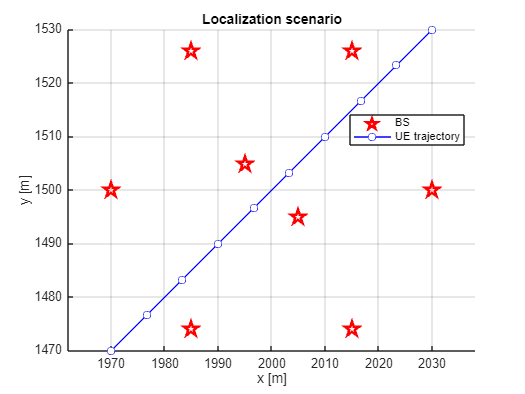

%% Localization
rng(42);
clc; clear; close all;

%% === 1) Geometry =======================================================
C = [2000, 1500];     % area center
halfLen = 30;         % half the trajectory length [m]
A = C - [halfLen, halfLen];
B = C + [halfLen, halfLen];

nPointsIn = 10;
xTraj_in = linspace(A(1), B(1), nPointsIn);
yTraj_in = linspace(A(2), B(2), nPointsIn);
truePosMatrix_in = [xTraj_in; yTraj_in]';
nPts = size(truePosMatrix_in,1);

%% === 2) Ring BSs + extra BSs ==========================================
nBSDefault = 6;                % num of BS's in ring
r_offset   = 30;               % cluster radius [m]
angles     = (0:nBSDefault-1)*(360/nBSDefault)*pi/180;

BS_pos   = C + [cos(angles)', sin(angles)'] * r_offset;
BS_extra = [1995,1505; 2005,1495];
BS_positions  = [BS_pos ; BS_extra];

anchorPos2D = BS_positions.';   % 2×N
nBS         = size(anchorPos2D,2);

figure; hold on; grid on; axis equal;
plot(anchorPos2D(1,:), anchorPos2D(2,:), 'rp', 'MarkerSize',12,'LineWidth',2);
plot(xTraj_in, yTraj_in, 'b-o', 'MarkerFaceColor','w');
xlabel('x [m]'); ylabel('y [m]');
title('Localization scenario');
legend('BS','UE trajectory','Location','best');


%% === 3) simulation parameters ===========================================
simParams = struct( ...
    'txPower',    10, ...       % dBm
    'txGain',     10, ...       % dBi
    'rxGain',     5, ...
    'systemLoss', 0, ...
    'fHz',        700e6, ...    % Hz
    'hBS',        25, ...       % m
    'hUT',        1.5, ...      % m
    'h_avg',      1.5, ...      % m (RMa avg building height; unused for UMa)
    'd0',         1, ...
    'BW',         10e6, ...
    'sigmaPL_LoS', 4, ...
    'sigmaPL_NLoS', 6, ...
    'scenario',  'uma', ...
    'useShadowing', true, ...
    'useFading',    true ... 
);

c = physconst('LightSpeed');
simParams.fGHz    = simParams.fHz / 1e9;
simParams.lambda  = c / simParams.fHz;
simParams.d_bp    = (4 * simParams.hBS * simParams.hUT * simParams.fHz) / c;

fprintf('Expected PL at 100 m (LOS, UMa) ≈ %.1f dB\n', 28 + 22*log10(100) + 20*log10(simParams.fGHz));

Expected PL at 100 m (LOS, UMa) ≈ 68.9 dB


fprintf('Breakpoint distance d_bp = %.2f m\n', simParams.d_bp);

Breakpoint distance d_bp = 350.24 m



%% === 4) Deterministic PL & per-(point,link) LOS (drawn once and held fixed for this run) ===
rssiDet       = zeros(nPointsIn, nBS);    % deterministic mean (dB)
losMatrix_in  = false(nPointsIn, nBS);    % LOS mask
sigmaShadow_link  = zeros(nPointsIn, nBS);    % per-link shadowing σ(dB)

for i = 1:nPointsIn
    tgtPos = truePosMatrix_in(i,:);
    for b = 1:nBS
        anchor = anchorPos2D(:,b).';
        d2D    = hypot(tgtPos(1)-anchor(1), tgtPos(2)-anchor(2));
        P_LOS  = calculate_LOS_probability(d2D, simParams.scenario, simParams.hUT);
        isLOS  = rand() < min(max(P_LOS,0),1);
        losMatrix_in(i,b) = isLOS;

        [P_det_dBm, ~] = rssiDeterministic(anchor, tgtPos, isLOS, simParams, simParams.scenario);
        rssiDet(i,b)    = P_det_dBm;

        sigmaShadow_link(i,b) = getShadowSigma(simParams.scenario, isLOS);  % 4/6 dB in UMa
    end
end

%% === 5) Packets: IID generation & BLOCK averaging ======================
% We evaluate multiple N, each summarized over B disjoint, independent blocks.
Ns   = [1e4 3e4 5e4 7e4 9e4 1e5];
B    = 50;                                  % independent blocks per N
Nmax = max(Ns);
Ktotal = B * Nmax;                           % packets we draw per link
K_10ln = 10/log(10);

% Pre-draw once: iid packet samples per link (mean rssiDet + noise)
rssiSamples_dBm = zeros(nPointsIn, nBS, Ktotal, 'single');
% rssiSamples_dBm holds received power in dBm (nPts × nBS × Ktotal), single precision
for i = 1:nPointsIn
    for b = 1:nBS
        Pdet   = rssiDet(i,b);
        isLOS  = losMatrix_in(i,b);

        % Shadowing (Gaussian in dB)
        if simParams.useShadowing
            shadow_dB = sigmaShadow_link(i,b) .* randn(1, Ktotal);
        else
            shadow_dB = zeros(1, Ktotal);
        end

        % Small-scale fading (generated in linear complex baseband; dB samples are biased & non-Gaussian)
        if simParams.useFading
            if isLOS
                KdB = 10;  K = 10^(KdB/10);
                phi   = 2*pi*rand(1, Ktotal);
                h_los = sqrt(K/(K+1)) * exp(1j*phi);
                h_nlos = sqrt(1/(2*(K+1))) * (randn(1,Ktotal) + 1j*randn(1,Ktotal));
                fad_dB = 10*log10( abs(h_los + h_nlos).^2);
            else
                h     = (randn(1,Ktotal) + 1j*randn(1,Ktotal))/sqrt(2);
                fad_dB = 10*log10( abs(h).^2 );
            end
        else
            fad_dB = zeros(1, Ktotal);
        end

        rssiSamples_dBm(i,b,:) = Pdet + shadow_dB + fad_dB;
    end
end

% Hold per-N block stats
rssiMean_blocks        = cell(numel(Ns),1);   % B × nPts × nBS
rssiVarEff_blocks_dB   = cell(numel(Ns),1);   % B × nPts × nBS

for a = 1:numel(Ns)
    N = Ns(a);
    rssiMean_B   = zeros(B, nPointsIn, nBS);
    rssiVar_B_dB = zeros(B, nPointsIn, nBS);

    if simParams.useFading
        % Average in linear power, then -> dB; delta method for Var(mean in dB)
        P_lin = 10.^(rssiSamples_dBm/10);  % nPts × nBS × Ktotal
        for bb = 1:B
            idx  = (bb-1)*N + (1:N);
            muP  = mean(P_lin(:,:,idx), 3);
            varP = var( P_lin(:,:,idx), 0, 3 );
            var_meanP = varP / N;

            rssiMean_blk = 10*log10(muP);
            var_dB       = (K_10ln^2) .* (var_meanP ./ (muP.^2));

            rssiMean_B(bb,:,:)   = rssiMean_blk;
            rssiVar_B_dB(bb,:,:) = var_dB;
        end

        % Approximate Jensen bias (lognormal, shadowing σ in dB)
        %     bias_shad_dB = (ln(10)/20) * sigma_shad_dB^2
        if simParams.useShadowing
            b_shad = zeros(B, nPointsIn, nBS);
            for i = 1:nPointsIn
                for j = 1:nBS
                    s = sigmaShadow_link(i,j);
                    b_shad(:,i,j) = (log(10)/20) * (s^2);
                end
            end
            rssiMean_B = rssiMean_B - b_shad;
        end
    else
        % Shadowing-only: average directly in dB; Var(mean)=Var(dB)/N
        for bb = 1:B
            idx  = (bb-1)*N + (1:N);
            mu_dB  = mean(rssiSamples_dBm(:,:,idx), 3);
            var_dB = var(  rssiSamples_dBm(:,:,idx), 0, 3 ) / N;

            rssiMean_B(bb,:,:)   = mu_dB;
            rssiVar_B_dB(bb,:,:) = var_dB;
        end
    end

    rssiMean_blocks{a}      = rssiMean_B;
    rssiVarEff_blocks_dB{a} = rssiVar_B_dB;
end

%% === 6) Residual diagnostics (choose N*, one block) =====================
idxN     = numel(Ns);           % pick largest N by default
N        = Ns(idxN);
bb0       = 1;                   % visualize block #1 (any 1..B)
idx      = (bb0-1)*N + (1:N);    % packet indices used by this block

% Note: Zero-mean sanity: mean≈0 by construction (residuals vs the same block mean);
rssiMean_thisBlock = mean(rssiSamples_dBm(:,:,idx), 3);        % nPts×nBS
residuals0         = rssiSamples_dBm(:,:,idx) - rssiMean_thisBlock;  % nPts×nBS×N
r0 = residuals0(:);
fprintf('residuals: mean = %.3f dB, std = %.3f dB\n', mean(r0), std(r0));

residuals: mean = 0.000 dB, std = 5.583 dB


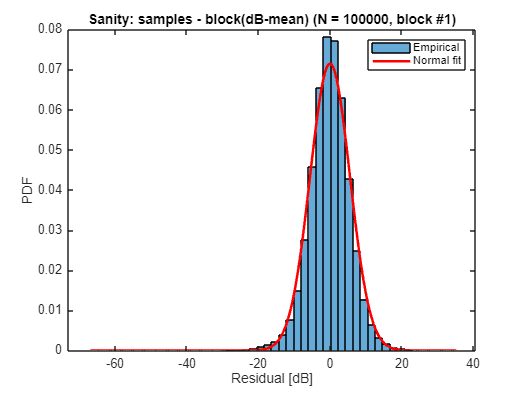


% --- Plot residual PDF for the zero-mean sanity check
figure; histogram(r0, 50, 'Normalization', 'pdf'); hold on;
xx = linspace(min(r0), max(r0), 200);
plot(xx, normpdf(xx, mean(r0), std(r0)), 'r-', 'LineWidth', 2);
xlabel('Residual [dB]'); ylabel('PDF');
title(sprintf('Sanity: samples - block(dB-mean) (N = %d, block #%d)', N, bb0));
legend('Empirical','Normal fit');



%% === 7) Residual analysis: (A) Shadowing-only (dB) and (B) Fading-only (linear & dB) ===
Nmc = N;                       % use the same packet count as the chosen block
KdB = 10; K = 10^(KdB/10);     % Rician K for LOS fading

%% (A) Shadowing-only in dB  → residuals vs rssiDet should be ~zero-mean
shadow_dB = zeros(nPointsIn, nBS, Nmc);
for i = 1:nPointsIn
    for b = 1:nBS
        sigmaPL = getShadowSigma(simParams.scenario, losMatrix_in(i,b));   % 4 dB (LOS) / 6 dB (NLOS)
        shadow_dB(i,b,:) = sigmaPL * randn(1,1,Nmc);          % iid Gaussian in dB
    end
end
rssi_shad_dB = rssiDet + shadow_dB;                           % nPts×nBS×Nmc (implicit expansion)
res_shad_dB  = rssi_shad_dB - rssiDet;                        % residuals vs deterministic PL (dB)

m_all  = mean(res_shad_dB(:));
s_all  = std(res_shad_dB(:));
maskLOS_rep  = repmat(losMatrix_in, [1 1 Nmc]);
maskNLOS_rep = ~maskLOS_rep;
vLOS   = std(res_shad_dB(maskLOS_rep));
vNLOS  = std(res_shad_dB(maskNLOS_rep));
fprintf('[Shadowing-only, dB] mean = %.3f dB (≈0), std = %.3f dB | LOS σ≈%.2f, NLOS σ≈%.2f\n', ...
        m_all, s_all, vLOS, vNLOS);

[Shadowing-only, dB] mean = -0.000 dB (≈0), std = 4.555 dB | LOS σ≈4.00, NLOS σ≈6.00


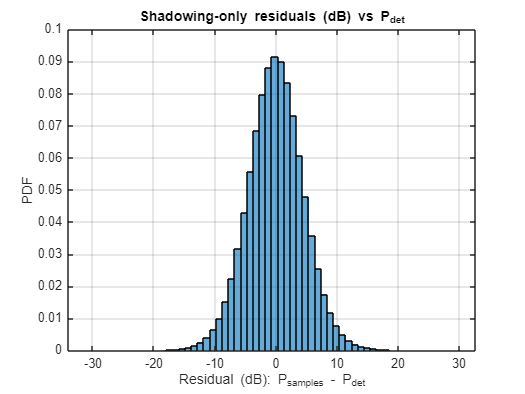


figure; histogram(res_shad_dB(:), 60, 'Normalization','pdf'); grid on; hold on;
xlabel('Residual (dB): P_{samples} - P_{det}'); ylabel('PDF');
title('Shadowing-only residuals (dB) vs P_{det}');


%% (B) Fading-only (zero-mean in LINEAR power; biased in dB)
fad_dB = zeros(nPointsIn, nBS, Nmc);
for i = 1:nPointsIn
    for b = 1:nBS
        if losMatrix_in(i,b)
            % Rician fading in baseband, then power in dB
            h_los  = sqrt(K/(K+1));
            h_nlos = sqrt(1/(2*(K+1))) * (randn(1,Nmc) + 1j*randn(1,Nmc));
            fad_dB(i,b,:) = 10*log10( abs(h_los + h_nlos).^2 );
        else
            % Rayleigh
            h = (randn(1,Nmc) + 1j*randn(1,Nmc))/sqrt(2);
            fad_dB(i,b,:) = 10*log10( abs(h).^2 );
        end
    end
end
rssi_fad_dB = rssiDet + fad_dB;

% Linear domain residuals (should be ~zero-mean per link)
P_lin = 10.^(rssi_fad_dB/10);             % convert to linear power
muP   = mean(P_lin, 3);                    % E[P] per link
res_lin = P_lin - muP;                     % zero-mean in linear
fprintf('[Fading-only, linear] mean = %.3g, std = %.3g (should be ~0 mean)\n', ...
        mean(res_lin(:)), std(res_lin(:)));

[Fading-only, linear] mean = 5.4e-21, std = 0.000173 (should be ~0 mean)



% dB residuals vs deterministic (expected negative mean for Rayleigh; K-dependent for Rician)
res_fad_dB = rssi_fad_dB - rssiDet;
m_dB = mean(res_fad_dB(:)); s_dB = std(res_fad_dB(:));
fprintf('[Fading-only, dB] mean = %.3f dB (Rayleigh ≈ -2.505 dB), std = %.3f dB\n', m_dB, s_dB);

[Fading-only, dB] mean = -0.911 dB (Rayleigh ≈ -2.505 dB), std = 3.347 dB


maskLOS3  = repmat(losMatrix_in, [1 1 Nmc]);
maskNLOS3 = ~maskLOS3;

res_fad_dB_LOS  = res_fad_dB(maskLOS3);
res_fad_dB_NLOS = res_fad_dB(maskNLOS3);

fprintf('Fading-only dB means: LOS ≈ %.3f dB (Rician, K=10), NLOS ≈ %.3f dB (Rayleigh ~ -2.505)\n', ...
        mean(res_fad_dB_LOS), mean(res_fad_dB_NLOS));

Fading-only dB means: LOS ≈ -0.414 dB (Rician, K=10), NLOS ≈ -2.506 dB (Rayleigh ~ -2.505)


fprintf('Fading-only dB stds:  LOS ≈ %.3f dB, NLOS ≈ %.3f dB\n', ...
        std(res_fad_dB_LOS), std(res_fad_dB_NLOS));

Fading-only dB stds:  LOS ≈ 1.998 dB, NLOS ≈ 5.568 dB


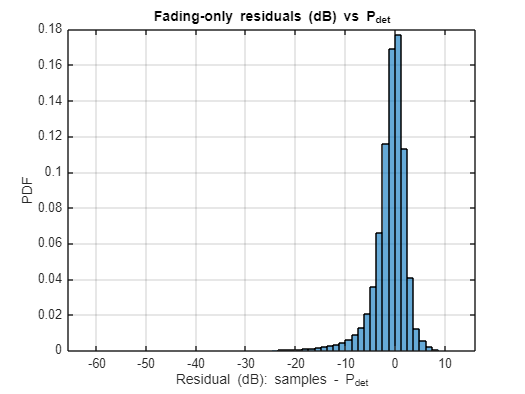


figure; histogram(res_fad_dB(:), 60, 'Normalization','pdf'); grid on; hold on;
xlabel('Residual (dB): samples - P_{det}'); ylabel('PDF');
title('Fading-only residuals (dB) vs P_{det}');



%% === Sanity tables: mean variance vs N, and sqrt-N trend ============
% (C) Mean of per-link variance of the block mean, averaged over blocks
meanVar_vsN = zeros(numel(Ns),1);
for a = 1:numel(Ns)
    V = rssiVarEff_blocks_dB{a};          % B × nPts × nBS
    meanVar_vsN(a) = mean(V(:));
end
disp(table(Ns(:), meanVar_vsN(:), 'VariableNames', {'N','MeanVar_dB2_overBlocks'}));

      N      MeanVar_dB2_overBlocks
    _____    ______________________

    10000           0.0077956      
    30000           0.0026831      
    50000           0.0016016      
    70000           0.0011577      
    90000          0.00090245      
    1e+05          0.00081129      




% (D) Shadowing-only: std( (avg over blocks of mean) - det * sqrt(N) ~ const
if ~simParams.useFading
    trend = zeros(numel(Ns),1);
    for a = 1:numel(Ns)
        mu_overB = squeeze(mean(rssiMean_blocks{a},1));          % nPts×nBS
        trend(a) = std( (mu_overB(:) - rssiDet(:)) ) * sqrt(Ns(a));
    end
    disp(table(Ns(:), trend(:), 'VariableNames', {'N','StdMeanTimesSqrtN_overBlocks'}));
end

%% === 8) SNR: Per-link receive SNR from block-mean RSSI ===============
kb = 1.38e-23; T = 290;
noisePower_W   = kb * T * simParams.BW;
noiseFigure_dB = 6;
noiseFloor_dBm = 10*log10(noisePower_W*1e3) + noiseFigure_dB;
simParams.noiseFloor_dBm = noiseFloor_dBm;
rssiMean_overB = squeeze(mean(rssiMean_blocks{idxN}, 1));
snrMatrix_dB  = rssiMean_overB - noiseFloor_dBm;
snrMatrix_lin = 10.^(snrMatrix_dB/10);
fprintf('Per-link SNR range (N=%d, avg over blocks): [%.1f, %.1f] dB\n', ...
        N, min(snrMatrix_dB(:)), max(snrMatrix_dB(:)));

Per-link SNR range (N=100000, avg over blocks): [39.1, 67.3] dB




%% === 9) Distances: true vs estimated from block means ===================
xBS = anchorPos2D(1,:); yBS = anchorPos2D(2,:);
xT  = xTraj_in(:);      yT  = yTraj_in(:);

dx = xT(:,ones(1,nBS)) - xBS(ones(nPointsIn,1),:);
dy = yT(:,ones(1,nBS)) - yBS(ones(nPointsIn,1),:);
trueDistMatrix_in = sqrt(dx.^2 + dy.^2);

% Use mean over blocks at max N for a stable estimate preview
estDistMatrix_in = rssi2distance_3gpp_uma(rssiMean_overB, losMatrix_in, simParams);

fprintf('True range:      [%.1f, %.1f] m\n', min(trueDistMatrix_in(:)), max(trueDistMatrix_in(:)));

True range:      [8.5, 71.8] m


fprintf('Estimated range: [%.1f, %.1f] m\n\n', min(estDistMatrix_in(:)), max(estDistMatrix_in(:)));

Estimated range: [8.5, 71.9] m




% LOS probability (theoretical) and counts against breakpoint
P_LoS = arrayfun(@(d) calculate_LOS_probability(d, simParams.scenario, simParams.hUT), ...
                 trueDistMatrix_in(:));
P_LoS = reshape(P_LoS, size(trueDistMatrix_in));
fprintf("Average P_LoS = %.2f → expected #LOS ≈ %.1f links\n", mean(P_LoS(:)), mean(P_LoS(:))*numel(P_LoS));

Average P_LoS = 0.81 → expected #LOS ≈ 64.6 links



d_vec   = trueDistMatrix_in(:);
los_vec = losMatrix_in(:);
nLinks  = numel(los_vec);

nLoS_total = sum(los_vec); nNLoS_total = nLinks - nLoS_total;
nLoS_lt_bp = sum( los_vec & (d_vec <  simParams.d_bp) );
nLoS_gt_bp = sum( los_vec & (d_vec >= simParams.d_bp) );
nNLoS_lt_bp= sum(~los_vec & (d_vec <  simParams.d_bp) );
nNLoS_gt_bp= sum(~los_vec & (d_vec >= simParams.d_bp) );

fprintf('Total links:            %3d\n', nLinks);

Total links:             80


fprintf('  LoS links:            %3d (%.1f%%)\n', nLoS_total,   100*nLoS_total/nLinks);

  LoS links:             61 (76.2%)


fprintf('    LoS & d < d_{bp}:   %3d\n', nLoS_lt_bp);

    LoS & d < d_{bp}:    61


fprintf('    LoS & d >= d_{bp}:  %3d\n\n', nLoS_gt_bp);

    LoS & d >= d_{bp}:    0



fprintf('  NLoS links:           %3d (%.1f%%)\n', nNLoS_total, 100*nNLoS_total/nLinks);

  NLoS links:            19 (23.8%)


fprintf('    NLoS & d < d_{bp}:  %3d\n', nNLoS_lt_bp);

    NLoS & d < d_{bp}:   19


fprintf('    NLoS & d >= d_{bp}: %3d\n', nNLoS_gt_bp);

    NLoS & d >= d_{bp}:   0



% Distance inversion errors (using mean-over-blocks at max N)
err = estDistMatrix_in - trueDistMatrix_in;
MAE_dist  = mean(abs(err(:)));
MSE_dist  = mean(err(:).^2);
RMSE_dist = sqrt(MSE_dist);
fprintf('Estimated distance errors:\n  MSE  = %.2f m^2\n  RMSE = %.2f m\n\n', MSE_dist, RMSE_dist);

Estimated distance errors:
  MSE  = 0.00 m^2
  RMSE = 0.02 m





%% === 10) GDOP ===========================================================
pCurrent = anchorPos2D.';    % N×2
tgt = truePosMatrix_in;
gd  = computeGDOP(pCurrent, tgt);
fprintf('Current @%.0fm cluster → median GDOP = %.2f, max GDOP = %.2f\n', r_offset, median(gd), max(gd));

Current @30m cluster → median GDOP = 0.72, max GDOP = 0.89


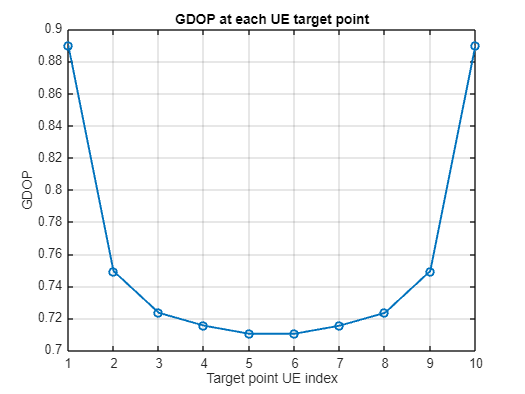

figure; plot(1:numel(gd), gd, 'o-','LineWidth',1.5); grid on;
xlabel('Target point UE index'); ylabel('GDOP'); title('GDOP at each UE target point');

% CRLB calculation
function [PEB, Cxy, traceC] = crlb_peb_from_sigmaZ(tgt_xy, anchorPos2D, losMask, SigmaZ_dB2_blk, simParams)
% CRLB in range domain using dB->range delta mapping at the TRUE (x,y).
% Returns:
%   PEB(Position Error Bound)   : nPts×1  (sqrt(trace(C)) per UE target point)
%   Cxy   : 2×2×nPts  full covariance per UE target point
%   traceC: nPts×1  trace(C) per UE target point
%
% Inputs:
%   tgt_xy          : nPts×2
%   anchorPos2D    : 2×nBS
%   losMask        : nPts×nBS logical
%   SigmaZ_dB2_blk : nPts×nBS (per-link VAR of block-mean in dB^2)
%   simParams      : struct with hBS, hUT, d_bp

    nPts = size(tgt_xy,1);
    nBS  = size(anchorPos2D,2);
    assert(all(size(SigmaZ_dB2_blk) == [nPts, nBS]), 'SigmaZ_dB2_blk must be nPts×nBS');

    dh   = simParams.hBS - simParams.hUT;
    ln10 = log(10);

    PEB    = zeros(nPts,1);
    traceC = zeros(nPts,1);
    Cxy    = zeros(2,2,nPts);

    for k = 1:nPts
        x = tgt_xy(k,1);  y = tgt_xy(k,2);

        % Geometry
        dx = x - anchorPos2D(1,:);
        dy = y - anchorPos2D(2,:);
        r  = sqrt(dx.^2 + dy.^2);                   % 2D range
        d3 = sqrt(r.^2 + dh^2);                     % 3D

        % Local 3GPP slopes 10n (dB/decade) for the subset of links
        beta10 = local_beta10_for_links([x,y], anchorPos2D, losMask(k,:), simParams.d_bp); % 1×nBS

        % Delta mapping: dPL/dd3 = beta10/(ln10·d3); dr/dd3 = d3/r ⇒ dr/dPL = (ln10/beta10)*(d3^2/r)
        dPL2r   = (ln10 ./ beta10) .* (d3.^2 ./ max(r,1e-9));        % 1×nBS
        sig2_r  = (dPL2r.^2) .* max(SigmaZ_dB2_blk(k,:), 1e-12);     % 1×nBS

        % Range Jacobian wrt [x,y]
        H = [dx./max(r,1e-9);  dy./max(r,1e-9)].';                  % nBS×2

        % Information & covariance
        W = diag(1 ./ sig2_r);                                      % nBS×nBS
        F = H.'*W*H;
        if rcond(F) < 1e-12, C = pinv(F); else, C = inv(F); end

        Cxy(:,:,k) = C;
        traceC(k)  = trace(C);
        PEB(k)     = sqrt(traceC(k));
    end
end

function beta10_vec = local_beta10_for_links(tgt_xy, anchorPos2D, losMask, dbp)
% local_beta10_for_links: Per-link 3GPP path-loss slope (10n) in dB/dec
%
% Inputs:
%   tgt_xy        : 1x2 or 2x1 [x, y] UE position
%   anchorPos2D  : 2xN_BS anchor positions
%   losMask      : 1xN_BS or Nx1 logical LOS/NLOS mask
%   dbp          : breakpoint distance (meters)
%   dh           : BS–UE height difference (meters)
%
% Output:
%   beta10_vec     : 1xN_BS slopes (dB/decade)

    % Ensure row vector for LOS mask
    losMask = losMask(:).';
    
    Nbs = size(anchorPos2D, 2);
    beta10_vec = 39.08 * ones(1, Nbs); % default: NLOS slope
    
    % Geometry: 3D distances to each anchor
    dx = tgt_xy(1) - anchorPos2D(1,:);
    dy = tgt_xy(2) - anchorPos2D(2,:);
    d2D = sqrt(dx.^2 + dy.^2);
    
    % LOS before breakpoint
    mask_LOS_pre = losMask & (d2D <= dbp);
    beta10_vec(mask_LOS_pre) = 22;
    
    % LOS after breakpoint
    mask_LOS_post = losMask & (d2D > dbp);
    beta10_vec(mask_LOS_post) = 40;
end

%% === 11) CRLB/PEB per block for each packet number, Ns ===========================================================
peb_cache   = cell(numel(Ns), B);   % each cell: nPts×1 PEB vector
Cxy_cache   = cell(numel(Ns), B);   % each cell: 2×2×nPts covariance per point
peb_rms_blk = nan(numel(Ns), B);    % RMS-PEB per block (scalar)

% Accumulators for pooled stats across blocks (used in §12)
pooled_sum_peb2 = zeros(numel(Ns),1);
pooled_sum_peb  = zeros(numel(Ns),1);
pooled_count    = zeros(numel(Ns),1);

for a = 1:numel(Ns)
    N = Ns(a);  % packets per block
    for bb = 1:B
        SigmaZ_dB2_blk = squeeze(rssiVarEff_blocks_dB{a}(bb,:,:));  % nPts×nBS
        tgt  = truePosMatrix_in;

        % Compute once and cache both PEB and Cxy
        [PEB, Cxy_blk] = crlb_peb_from_sigmaZ(tgt, anchorPos2D, ...
                                              losMatrix_in, SigmaZ_dB2_blk, simParams);

        peb_cache{a,bb} = PEB;            % nPts×1
        Cxy_cache{a,bb} = Cxy_blk;        % 2×2×nPts
        peb_rms_blk(a,bb) = sqrt(mean(PEB.^2));   % RMS-PEB for this block

        % pooled accumulators for §D (avoid recompute)
        pooled_sum_peb2(a) = pooled_sum_peb2(a) + sum(PEB.^2);
        pooled_sum_peb(a)  = pooled_sum_peb(a)  + sum(PEB);
        pooled_count(a)    = pooled_count(a)    + numel(PEB);

        fprintf('CRLB: N=%d | Block %d — RMS-PEB = %.3f m\n', N, bb, peb_rms_blk(a,bb));
    end
end

CRLB: N=10000 | Block 1 — RMS-PEB = 0.257 m
CRLB: N=10000 | Block 2 — RMS-PEB = 0.261 m
CRLB: N=10000 | Block 3 — RMS-PEB = 0.258 m
CRLB: N=10000 | Block 4 — RMS-PEB = 0.264 m
CRLB: N=10000 | Block 5 — RMS-PEB = 0.260 m
CRLB: N=10000 | Block 6 — RMS-PEB = 0.262 m
CRLB: N=10000 | Block 7 — RMS-PEB = 0.260 m
CRLB: N=10000 | Block 8 — RMS-PEB = 0.261 m
CRLB: N=10000 | Block 9 — RMS-PEB = 0.261 m
CRLB: N=10000 | Block 10 — RMS-PEB = 0.262 m
CRLB: N=10000 | Block 11 — RMS-PEB = 0.260 m
CRLB: N=10000 | Block 12 — RMS-PEB = 0.262 m
CRLB: N=10000 | Block 13 — RMS-PEB = 0.260 m
CRLB: N=10000 | Block 14 — RMS-PEB = 0.262 m
CRLB: N=10000 | Block 15 — RMS-PEB = 0.263 m
CRLB: N=10000 | Block 16 — RMS-PEB = 0.263 m
CRLB: N=10000 | Block 17 — RMS-PEB = 0.261 m
CRLB: N=10000 | Block 18 — RMS-PEB = 0.259 m
CRLB: N=10000 | Block 19 — RMS-PEB = 0.259 m
CRLB: N=10000 | Block 20 — RMS-PEB = 0.260 m
CRLB: N=10000 | Block 21 — RMS-PEB = 0.262 m
CRLB: N=10000 | Block 22 — RMS-PEB = 0.260 m
CRLB: N=10000 | Blo


%% === 12) CRLB/PEB block summaries ===========================================================
% --- Collect PEB results ---
fprintf('\n=== CRLB/PEB Summary over all Ns ===\n');


=== CRLB/PEB Summary over all Ns ===


for a = 1:numel(Ns)
    N = Ns(a);

    peb_blk = peb_rms_blk(a,:);   % RMS-PEB per block (m)

    [peb_min, bb_min] = min(peb_blk, [], 'omitnan');
    [peb_max, bb_max] = max(peb_blk, [], 'omitnan');
    peb_mean   = mean(peb_blk,   'omitnan');
    peb_median = median(peb_blk, 'omitnan');
    peb_overall = sqrt(mean(peb_blk.^2, 'omitnan'));   % pooled RMS

    fprintf(['CRLB/PEB @N=%-7g | overall RMS-PEB=%.3f m | mean=%.3f | median=%.3f | ', ...
             'min=%.3f (bb=%d) | max=%.3f (bb=%d)\n'], ...
            N, peb_overall, peb_mean, peb_median, peb_min, bb_min, peb_max, bb_max);
end

CRLB/PEB @N=10000   | overall RMS-PEB=0.260 m | mean=0.260 | median=0.260 | min=0.256 (bb=33) | max=0.265 (bb=46)
CRLB/PEB @N=30000   | overall RMS-PEB=0.151 m | mean=0.151 | median=0.151 | min=0.150 (bb=42) | max=0.153 (bb=46)
CRLB/PEB @N=50000   | overall RMS-PEB=0.117 m | mean=0.117 | median=0.117 | min=0.116 (bb=11) | max=0.118 (bb=28)
CRLB/PEB @N=70000   | overall RMS-PEB=0.099 m | mean=0.099 | median=0.099 | min=0.098 (bb=40) | max=0.100 (bb=38)
CRLB/PEB @N=90000   | overall RMS-PEB=0.087 m | mean=0.087 | median=0.087 | min=0.087 (bb=4) | max=0.088 (bb=30)
CRLB/PEB @N=100000  | overall RMS-PEB=0.083 m | mean=0.083 | median=0.083 | min=0.082 (bb=4) | max=0.084 (bb=27)



% --- Collect MSE results ---
fprintf('\n=== CRLB/MSE Summary over all Ns ===\n');


=== CRLB/MSE Summary over all Ns ===


for a = 1:numel(Ns)
    N = Ns(a);

    mse_blk = nan(1,B);
    for bb = 1:B
        Cxy_blk = Cxy_cache{a,bb};
        if isempty(Cxy_blk), continue; end
        tr_all = squeeze(Cxy_blk(1,1,:) + Cxy_blk(2,2,:));   % nPts×1, m^2
        mse_blk(bb) = mean(tr_all, 'omitnan');
    end

    [mse_min, bb_mmin] = min(mse_blk, [], 'omitnan');
    [mse_max, bb_mmax] = max(mse_blk, [], 'omitnan');
    mse_mean   = mean(mse_blk,   'omitnan');
    mse_median = median(mse_blk, 'omitnan');
    mse_overall = mean(mse_blk,  'omitnan');   % pooled mean MSE

    fprintf(['CRLB/MSE @N=%-7g | overall MSE=%.4f m^2 | mean=%.4f | median=%.4f | ', ...
             'min=%.4f (bb=%d) | max=%.4f (bb=%d)\n'], ...
            N, mse_overall, mse_mean, mse_median, mse_min, bb_mmin, mse_max, bb_mmax);
end

CRLB/MSE @N=10000   | overall MSE=0.0677 m^2 | mean=0.0677 | median=0.0676 | min=0.0653 (bb=33) | max=0.0704 (bb=46)
CRLB/MSE @N=30000   | overall MSE=0.0228 m^2 | mean=0.0228 | median=0.0228 | min=0.0224 (bb=42) | max=0.0235 (bb=46)
CRLB/MSE @N=50000   | overall MSE=0.0137 m^2 | mean=0.0137 | median=0.0137 | min=0.0135 (bb=11) | max=0.0140 (bb=28)
CRLB/MSE @N=70000   | overall MSE=0.0098 m^2 | mean=0.0098 | median=0.0098 | min=0.0097 (bb=40) | max=0.0101 (bb=38)
CRLB/MSE @N=90000   | overall MSE=0.0076 m^2 | mean=0.0076 | median=0.0076 | min=0.0075 (bb=4) | max=0.0078 (bb=30)
CRLB/MSE @N=100000  | overall MSE=0.0069 m^2 | mean=0.0069 | median=0.0069 | min=0.0068 (bb=4) | max=0.0070 (bb=27)


%% === 13) Range-domain WLS with per-iteration reweighting ===========================================================
k = nBS;

rmse_range_vsN      = zeros(numel(Ns),1);   % overall (avg across blocks & pts)
rmse_blocks_vsN     = nan(numel(Ns), B);    % per-block RMSE for each N
p_range_blocks      = cell(numel(Ns), B);   % store per-block estimates

for a = 1:numel(Ns)
    N = Ns(a);
    mu_dB_blk = rssiMean_blocks{a};           % B × nPts × nBS
    Sig_dB2   = rssiVarEff_blocks_dB{a};      % B × nPts × nBS

    % squared error per block × point
    se_blocks_allpts = zeros(B, nPointsIn);

    for bb = 1:B
        % ---- Extract block data ----
        rssi_blk   = squeeze(mu_dB_blk(bb,:,:));   % nPts × nBS (dB)
        sigma_dB2  = squeeze(Sig_dB2(bb,:,:));     % nPts × nBS (dB^2)

        % ---- RSSI → ranges ONCE per block (all UE target points, all anchors) ----
        d_hat = rssi2distance_3gpp_uma(rssi_blk, losMatrix_in, simParams);  % nPts × nBS

        p_est_blk = zeros(nPointsIn,2);

        for i = 1:nPointsIn
            % ---- choose k nearest anchors by observed range ----
            [~,ord] = sort(d_hat(i,:));
            idxK    = ord(1:min(k, numel(ord)));

            r_obs    = d_hat(i, idxK);                % observed ranges
            Axy      = anchorPos2D(:, idxK).';        % k×2
            losMaskK = losMatrix_in(i, idxK);         % 1×k
            sigK     = sigma_dB2(i, idxK);            % 1×k

            % ---- initial guess: centroid ----
            p0 = centroid_seed(d_hat(i,:), anchorPos2D);

            % ---- WLS refinement ----
            p_est = range_wls_gn_reweighted(r_obs, Axy, sigK, losMaskK, simParams, p0);

            % ---- store estimate ----
            p_est_blk(i,:) = p_est;

            % ---- squared error vs truth ----
            se_blocks_allpts(bb,i) = (p_est(1) - truePosMatrix_in(i,1))^2 + ...
                                     (p_est(2) - truePosMatrix_in(i,2))^2;
        end

        % ---- per-block RMSE ----
        rmse_blocks_vsN(a,bb) = sqrt( mean( se_blocks_allpts(bb,:) ) );
        p_range_blocks{a,bb}  = p_est_blk;
    end

    % ---- overall RMSE for this N (avg over blocks & UE target points) ----
    rmse_range_vsN(a) = sqrt( mean( se_blocks_allpts(:) ) );

    % ---- print compact summary ----
    rb = rmse_blocks_vsN(a, :);
    rb_mean = mean(rb, 'omitnan');
    rb_med  = median(rb, 'omitnan');
    [rb_min, bb_min] = min(rb, [], 'omitnan');
    [rb_max, bb_max] = max(rb, [], 'omitnan');
    rb_std  = std(rb, 0, 'omitnan');

    fprintf(['Range-WLS (reweighted) @N=%d (k=%d): overall=%.3f | ', ...
            'per-block RMSE → mean=%.3f, median=%.3f, ', ...
             'min=%.3f (bb=%d), max=%.3f (bb=%d), std=%.3f\n'], ...
             N, k, rmse_range_vsN(a), ...
            rb_mean, rb_med, rb_min, bb_min, rb_max, bb_max, rb_std);
end

Range-WLS (reweighted) @N=10000 (k=8): overall=0.265 | per-block RMSE → mean=0.262, median=0.262, min=0.177 (bb=4), max=0.374 (bb=44), std=0.040
Range-WLS (reweighted) @N=30000 (k=8): overall=0.153 | per-block RMSE → mean=0.150, median=0.149, min=0.086 (bb=34), max=0.218 (bb=10), std=0.030
Range-WLS (reweighted) @N=50000 (k=8): overall=0.120 | per-block RMSE → mean=0.118, median=0.116, min=0.077 (bb=36), max=0.171 (bb=6), std=0.019
Range-WLS (reweighted) @N=70000 (k=8): overall=0.099 | per-block RMSE → mean=0.098, median=0.098, min=0.068 (bb=39), max=0.126 (bb=30), std=0.017
Range-WLS (reweighted) @N=90000 (k=8): overall=0.087 | per-block RMSE → mean=0.086, median=0.087, min=0.054 (bb=9), max=0.120 (bb=45), std=0.014
Range-WLS (reweighted) @N=100000 (k=8): overall=0.082 | per-block RMSE → mean=0.081, median=0.078, min=0.049 (bb=33), max=0.122 (bb=15), std=0.016


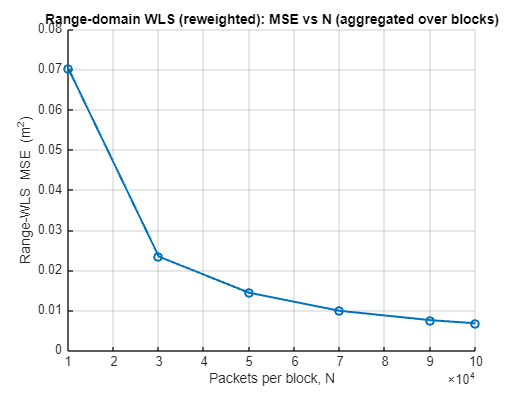

%% === 14) WLS plots and visualizations ===========================================================
% (A)--- PLOT: overall MSE error vs per-block spread ---
mse_overall_vsN = rmse_range_vsN.^2;          % 1×|Ns|
mse_blocks_vsN  = rmse_blocks_vsN.^2;         % |Ns|×B

figure; hold on; grid on;
plot(Ns, mse_overall_vsN, 'o-','LineWidth',1.6);
xlabel('Packets per block, N'); ylabel('Range-WLS MSE (m^2)');
title('Range-domain WLS (reweighted): MSE vs N (aggregated over blocks)');

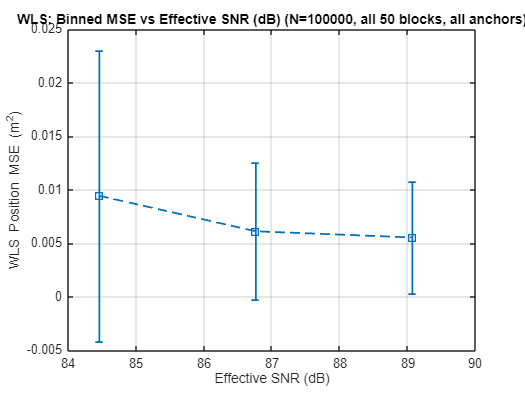


%% === WLS: MSE vs Effective SNR, aggregated over ALL blocks at one N ===
targetN = 1e5;                                     % <--- pick N
a_use   = find(Ns == targetN, 1);
assert(~isempty(a_use), 'targetN not found in Ns');

dh   = simParams.hBS - simParams.hUT;
ln10 = log(10);

% Geometry at TRUE UE target points (used by all blocks)
dx  = truePosMatrix_in(:,1) - anchorPos2D(1,:);
dy  = truePosMatrix_in(:,2) - anchorPos2D(2,:);
r2D = sqrt(dx.^2 + dy.^2);
d3D = sqrt(r2D.^2 + dh^2);

% 3GPP piecewise slopes 10n per link at TRUE (x,y)
beta10 = zeros(nPts, nBS);
for k = 1:nPts
    beta10(k,:) = local_beta10_for_links(truePosMatrix_in(k,:), anchorPos2D, ...
                                         losMatrix_in(k,:), simParams.d_bp);
end

% dB→range delta mapping factor (link-wise, geometry-only)
dPL2r_geom = (ln10 ./ beta10) .* (d3D.^2 ./ max(r2D,1e-9));   % nPts×nBS

% (B)--- PLOT: WLS: MSE vs Effective SNR(linear and dB)---
% Heuristic scalar: EffSNR = mean per-link SNR (linear) / σ_eff,pos^2 from CRLB (avg per-axis).

allEffSNR_WLS = [];   % scalar effective SNR per (UE target point, block) — linear first, convert to dB for plotting
allMSE        = [];   % matching WLS MSE per UE target point (m^2)

for bb = 1:B
    % WLS positions for this block
    posMeas = p_range_blocks{a_use, bb};     % nPts×2
    if isempty(posMeas), continue; end

    % Per-link variance of block-mean RSSI in dB^2 (this block)
    SigmaZ_dB2_blk = reshape(rssiVarEff_blocks_dB{a_use}(bb,:,:), [nPts, nBS]);

    % Map dB-variance -> range-variance (reuse geometry-only Jacobian)
    sigma_r2 = (dPL2r_geom.^2) .* max(SigmaZ_dB2_blk, 1e-12);    % nPts×nBS

    % Per-link SNR for this block (from this block's mean RSSI)
    rssi_blk = squeeze(rssiMean_blocks{a_use}(bb,:,:));          % nPts×nBS (dBm)
    snr_dB   = rssi_blk - simParams.noiseFloor_dBm;              % nPts×nBS
    SNR_lin  = 10.^(snr_dB/10);                                  % nPts×nBS

    % Position-domain CRLB for this block → effective sigma^2 per UE target point
    sigma_eff_pos2 = zeros(nPts,1);
    for k = 1:nPts
        rk = max(r2D(k,:), 1e-9);
        Hk = [dx(k,:)./rk;  dy(k,:)./rk].';                      % nBS×2
        Wk = diag( 1 ./ sigma_r2(k,:) );                         % nBS×nBS
        Fk = Hk.' * Wk * Hk;
        Ck = inv(Fk + 1e-15*eye(2));
        sigma_eff_pos2(k) = 0.5 * trace(Ck);                     % avg per-axis variance
    end

    % Effective SNR scalar (linear) → will be converted to dB for binning
    SNR_scalar = mean(SNR_lin, 2);                               % nPts×1 (linear)
    EffSNR_blk = SNR_scalar ./ max(sigma_eff_pos2, 1e-18);       % nPts×1 (linear)

    % WLS MSE for this block (reuse posMeas)
    e_WLS  = hypot(posMeas(:,1) - truePosMatrix_in(:,1), ...
                   posMeas(:,2) - truePosMatrix_in(:,2));
    MSE_WLS = e_WLS.^2;

    % Append
    allEffSNR_WLS = [allEffSNR_WLS; EffSNR_blk(:)];
    allMSE        = [allMSE;        MSE_WLS(:)];
end

% Keep finite pairs
mask = isfinite(allEffSNR_WLS) & (allEffSNR_WLS>0) & isfinite(allMSE);
eff_dB = 10*log10(allEffSNR_WLS(mask));
mse    = allMSE(mask);

% ---------- Binned mean±std of MSE vs effective SNR (dB) ----------
numBins   = 3;
xmin = min(eff_dB); xmax = max(eff_dB);
if xmax <= xmin
    edges = (xmin-1):2:(xmin+9);
else
    edges = linspace(xmin, xmax, numBins+1);
    if numel(edges)<3, edges = (xmin-1):2:(xmax+1); end
end
[~,~,binIdx] = histcounts(eff_dB, edges);
centers = edges(1:end-1) + diff(edges)/2;

m = nan(numBins,1); s = nan(numBins,1);
for b = 1:numBins
    inb = (binIdx == b);
    if any(inb)
        m(b) = mean(mse(inb), 'omitnan');
        s(b) = std( mse(inb), 'omitnan');
    end
end

figure; errorbar(centers, m, s, 's--','LineWidth',1.4,'MarkerSize',7); grid on;
xlabel('Effective SNR (dB)');
ylabel('WLS Position MSE (m^2)');
title(sprintf('WLS: Binned MSE vs Effective SNR (dB) (N=%d, all %d blocks, all anchors)', Ns(a_use), B));

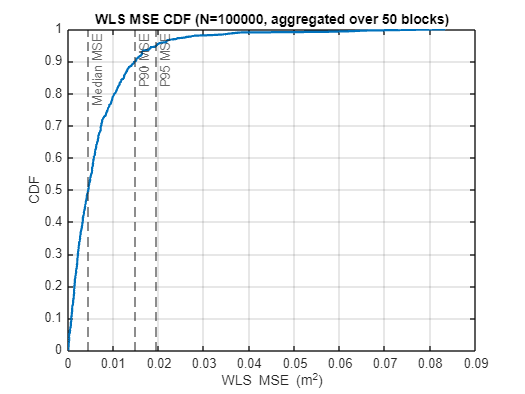


% (C)--- PLOT: CDF of WLS error aggregated over all blocks (fixed N)---
mse_all = [];   % collect per-UE target point MSE samples across blocks
for bb = 1:B
    posMeas = p_range_blocks{a_use, bb};    % nPts×2
    if isempty(posMeas), continue; end
    e = hypot(posMeas(:,1) - truePosMatrix_in(:,1), ...
              posMeas(:,2) - truePosMatrix_in(:,2));
    mse_all = [mse_all; e.^2];              % append MSE samples
end

% Summary stats (MSE)
MSE_mean = mean(mse_all);
RMSE     = sqrt(MSE_mean);
medMSE   = median(mse_all);
p90MSE   = prctile(mse_all, 90);
p95MSE   = prctile(mse_all, 95);

[Fi_mse, Xi_mse] = ecdf(mse_all);
figure; plot(Xi_mse, Fi_mse, 'LineWidth',1.8); grid on; hold on;
xline(medMSE,'--','Median MSE'); xline(p90MSE,'--','P90 MSE'); xline(p95MSE,'--','P95 MSE');
xlabel('WLS MSE (m^2)'); ylabel('CDF');

title(sprintf('WLS MSE CDF (N=%d, aggregated over %d blocks)', Ns(a_use), B));

fprintf('[WLS @N=%d] MSE(mean)=%.4f m^2 | RMSE=%.3f m | Median MSE=%.4f | P90=%.4f | P95=%.4f | n=%d\n', ...
        Ns(a_use), MSE_mean, RMSE, medMSE, p90MSE, p95MSE, numel(mse_all));

[WLS @N=100000] MSE(mean)=0.0068 m^2 | RMSE=0.082 m | Median MSE=0.0045 | P90=0.0149 | P95=0.0196 | n=500



% (D)--- PRINTS: Pooled CRLB across blocks vs WLS RMSE + MSE---
% RMSE
pooled_rms_peb_vsN = sqrt( pooled_sum_peb2 ./ max(pooled_count,1) );
mean_peb_vsN       =        pooled_sum_peb  ./ max(pooled_count,1);

% MSE
pooled_mse_peb_vsN = pooled_sum_peb2 ./ max(pooled_count,1);   % pooled mean variance
mse_range_vsN      = rmse_range_vsN.^2;                        % square the overall RMSE

T_rmse = table(Ns(:), rmse_range_vsN(:), pooled_rms_peb_vsN(:), ...
               'VariableNames', {'Npackets','WLS_RMSE','CRLB_RMS_PEB'});
disp('RMSE comparison'); disp(T_rmse);

RMSE comparison
    Npackets    WLS_RMSE    CRLB_RMS_PEB
    ________    ________    ____________

     10000       0.26511       0.26015  
     30000       0.15297       0.15105  
     50000       0.11988       0.11716  
     70000      0.099389      0.099108  
     90000      0.086926      0.087446  
     1e+05      0.082295      0.082972  




T_mse = table(Ns(:), mse_range_vsN(:), pooled_mse_peb_vsN(:), ...
              'VariableNames', {'Npackets','WLS_MSE','CRLB_MSE_PEB'});
disp('MSE comparison'); disp(T_mse);

MSE comparison
    Npackets     WLS_MSE     CRLB_MSE_PEB
    ________    _________    ____________

     10000       0.070283      0.067677  
     30000       0.023399      0.022816  
     50000       0.014371      0.013726  
     70000      0.0098783     0.0098224  
     90000      0.0075561     0.0076467  
     1e+05      0.0067724     0.0068843  



 
% (E)--- PRINTS: % Efficiency metric = RMSE^2 / PEB^2 
efficiency_rmse_vsN = (rmse_range_vsN.^2) ./ (pooled_rms_peb_vsN.^2);
efficiency_mse_vsN  = mse_range_vsN ./ pooled_mse_peb_vsN;

fprintf('Efficiency metric\n');

Efficiency metric


disp(table(Ns(:), efficiency_rmse_vsN, efficiency_mse_vsN, ...
    'VariableNames', {'Npackets','Eff_RMSE2_over_PEB2','Eff_MSE_over_E[PEB2]'}));

    Npackets    Eff_RMSE2_over_PEB2    Eff_MSE_over_E[PEB2]
    ________    ___________________    ____________________

     10000             1.0385                 1.0385       
     30000             1.0256                 1.0256       
     50000              1.047                  1.047       
     70000             1.0057                 1.0057       
     90000            0.98815                0.98815       
     1e+05            0.98375                0.98375       



%% === 15) EKF Fusion (range-WLS + DoA) across all blocks (fixed N)======================================================
overallEKF_vsN      = zeros(numel(Ns),1);
rmseKF_blocks_vsN   = nan(numel(Ns), B);
p_kf_blocks_all     = cell(numel(Ns), B);
allErrEKF_allNs     = cell(numel(Ns),1);
allEffSNR_EKF_allNs = cell(numel(Ns),1);

for a = 1:numel(Ns)
    [overallRMSE_KF, rmseKF_blocks, allErrEKF, p_kf_blocks, allEffSNR_EKF] = ...
        ekf_fuse_blocks_forN(a, B, Ns, anchorPos2D, truePosMatrix_in, losMatrix_in, ...
                             simParams, rssiMean_blocks, rssiVarEff_blocks_dB, ...
                             p_range_blocks, Cxy_cache);

    overallEKF_vsN(a)        = overallRMSE_KF;
    rmseKF_blocks_vsN(a,:)   = rmseKF_blocks;
    allErrEKF_allNs{a}       = allErrEKF;
    allEffSNR_EKF_allNs{a}   = allEffSNR_EKF;   % <— store it
    for bb = 1:B, p_kf_blocks_all{a,bb} = p_kf_blocks{bb}; end

    rb = rmseKF_blocks;
    rb_mean = mean(rb,'omitnan');
    rb_med  = median(rb,'omitnan');
    [rb_min, bb_min] = min(rb, [], 'omitnan');
    [rb_max, bb_max] = max(rb, [], 'omitnan');
    rb_std  = std(rb, 0, 'omitnan');

    fprintf(['[EKF Fusion RMSE] @N=%-7g: overall=%.3f | per-block RMSE → ', ...
             'mean=%.3f, median=%.3f, min=%.3f (bb=%d), max=%.3f (bb=%d), std=%.3f\n'], ...
            Ns(a), overallRMSE_KF, rb_mean, rb_med, rb_min, bb_min, rb_max, bb_max, rb_std);
end

[EKF Fusion RMSE] @N=10000  : overall=0.229 | per-block RMSE → mean=0.225, median=0.220, min=0.141 (bb=4), max=0.358 (bb=29), std=0.043
[EKF Fusion RMSE] @N=30000  : overall=0.138 | per-block RMSE → mean=0.135, median=0.135, min=0.077 (bb=32), max=0.210 (bb=10), std=0.029
[EKF Fusion RMSE] @N=50000  : overall=0.109 | per-block RMSE → mean=0.108, median=0.108, min=0.073 (bb=36), max=0.154 (bb=6), std=0.017
[EKF Fusion RMSE] @N=70000  : overall=0.091 | per-block RMSE → mean=0.090, median=0.093, min=0.056 (bb=28), max=0.125 (bb=30), std=0.016
[EKF Fusion RMSE] @N=90000  : overall=0.081 | per-block RMSE → mean=0.080, median=0.082, min=0.051 (bb=9), max=0.110 (bb=34), std=0.014
[EKF Fusion RMSE] @N=100000 : overall=0.077 | per-block RMSE → mean=0.076, median=0.075, min=0.048 (bb=33), max=0.110 (bb=15), std=0.014


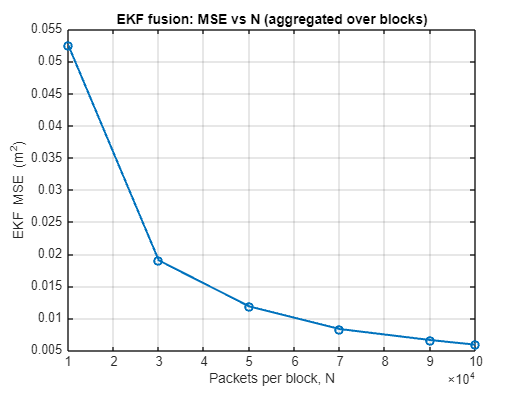


% --- Store MSE ---
overallEKF_MSE_vsN = zeros(numel(Ns),1);

for a = 1:numel(Ns)
    allErrKF = allErrEKF_allNs{a};       % per-sample errors at this N
    mse_val  = mean(allErrKF.^2);        % mean squared error
    overallEKF_MSE_vsN(a) = mse_val;
end

% --- Plot: EKF MSE vs N ---
figure; 
plot(Ns, overallEKF_MSE_vsN, 'o-','LineWidth',1.6); grid on;
xlabel('Packets per block, N'); 
ylabel('EKF MSE (m^2)');
title('EKF fusion: MSE vs N (aggregated over blocks)');

%% === 16) EKF plots and visualizations ===========================================================
% reuses targetN(1e5) and a_use defined globally
eff_lin = allEffSNR_EKF_allNs{a_use}(:);    % effective SNR (linear)
err_e   = allErrEKF_allNs{a_use}(:);        % EKF errors (m)

mask = isfinite(eff_lin) & eff_lin>0 & isfinite(err_e);
eff_lin = eff_lin(mask);
err_e   = err_e(mask);

% --- Scalars (error & MSE summaries) ---
se     = err_e.^2;                  % squared error (m^2)
mse_e  = mean(se);                  % MSE (m^2)
rmse_e = sqrt(mse_e);               % RMSE (m)
med_e  = median(err_e);
p90_e  = prctile(err_e,90);
p95_e  = prctile(err_e,95);

% percentiles in MSE space
med_se = median(se);
p90_se = prctile(se,90);
p95_se = prctile(se,95);

fprintf(['[EKF summary @N=%d] RMSE=%.3f m | MSE=%.4f m^2 | ', ...
         'median(|e|)=%.3f | P90(|e|)=%.3f | P95(|e|)=%.3f | n=%d\n'], ...
        Ns(a_use), rmse_e, mse_e, med_e, p90_e, p95_e, numel(err_e));

[EKF summary @N=100000] RMSE=0.077 m | MSE=0.0059 m^2 | median(|e|)=0.063 | P90(|e|)=0.115 | P95(|e|)=0.132 | n=500


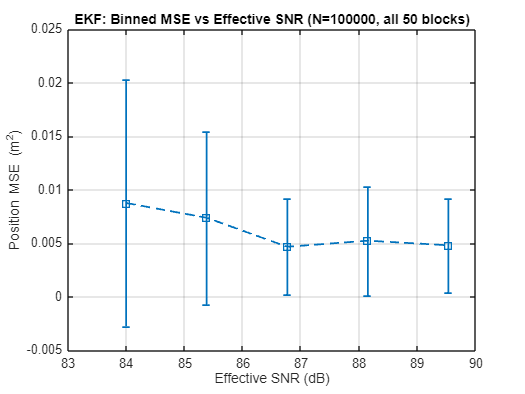


% (A)--- PLOT: KF Error vs Effective SNR (dB)---
snr_eff_dB = 10*log10(eff_lin);
numBins = 5;

xmin = min(snr_eff_dB); xmax = max(snr_eff_dB);
if xmax <= xmin
    edges = (xmin-1):2:(xmin+9);
else
    edges = linspace(xmin, xmax, numBins+1);
    if numel(edges) < 3
        edges = (xmin-1):2:(xmax+1);
    end
end

[~,~,binIdx] = histcounts(snr_eff_dB, edges);
centers = edges(1:end-1) + diff(edges)/2;

m = nan(numBins,1); s = nan(numBins,1); counts = zeros(numBins,1);
for b = 1:numBins
    inb = (binIdx == b);
    counts(b) = nnz(inb);
    if counts(b) > 0
        % MSE in the bin
        m(b) = mean(se(inb), 'omitnan');
        s(b) = std( se(inb), 'omitnan');
    end
end

figure; errorbar(centers, m, s, 's--','LineWidth',1.4,'MarkerSize',7); grid on;
xlabel('Effective SNR (dB)');
ylabel('Position MSE (m^2)');
title(sprintf('EKF: Binned MSE vs Effective SNR (N=%d, all %d blocks)', Ns(a_use), B));

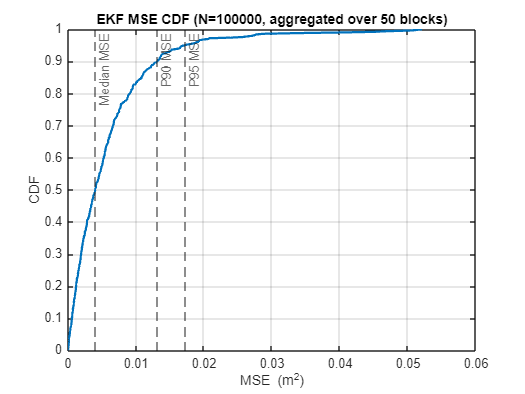


% (B)--- PLOT: CDF of EKF error---
[Fi_mse, Xi_mse] = ecdf(se);
figure; plot(Xi_mse, Fi_mse, 'LineWidth',1.8); grid on; hold on;
xline(med_se,'--','Median MSE'); xline(p90_se,'--','P90 MSE'); xline(p95_se,'--','P95 MSE');
xlabel('MSE (m^2)');
ylabel('CDF');
title(sprintf('EKF MSE CDF (N=%d, aggregated over %d blocks)', Ns(a_use), B));

%% ====================================================================================
%% === 17) Helper functions ===========================================================
%% ====================================================================================

function [P_det_dBm, betaN_exp] = rssiDeterministic(anchorPos, tgtPos, isLOS, simParams, scenario)
% NOTE: % betaN_exp returned here is the path-loss exponent n (unitless)
d2D = hypot(tgtPos(1)-anchorPos(1), tgtPos(2)-anchorPos(2));
d3D = hypot(d2D, (simParams.hBS - simParams.hUT));
fGHz = simParams.fHz/1e9;
if isLOS
    if d3D <= simParams.d_bp, betaN_exp = 2.2; else, betaN_exp = 4.0; end
    PL = getLOSpathLoss(scenario, d2D, d3D, simParams.d_bp, fGHz, simParams.hBS, simParams.hUT, simParams.h_avg);
else
    betaN_exp = 39.08/10; % 3.908
    [PL_LOS, PL_NLOS] = getNLOSpathLoss(scenario, d2D, d3D, simParams.d_bp, fGHz, simParams.hBS, simParams.hUT, simParams.h_avg);
    PL = max(PL_LOS, PL_NLOS);
end
P_det_dBm = simParams.txPower + simParams.txGain + simParams.rxGain - simParams.systemLoss - PL;
end

function P_LOS = calculate_LOS_probability(d2D, scenario, hUT)
switch lower(scenario)
    case 'uma'
        if d2D <= 18
            P_LOS = 1;
        else
            C_hUT = 0;
            if (13 < hUT) && (hUT <= 23)
                C_hUT = ((hUT - 13)/10)^1.5;
            end
            P_LOS = (18/d2D + exp(-d2D/63) * (1 - 18/d2D)) * ...
                    (1 + C_hUT * (5/4) * (d2D/100)^3 * exp(-d2D/150));
        end
    case 'rma'
        if d2D <= 10, P_LOS = 1; else, P_LOS = exp(-((d2D - 10)/1000)); end
    case 'inh'
        if d2D <= 1.2, P_LOS = 1; else, P_LOS = exp(-(d2D - 1.2)/4.7); end
    otherwise
        P_LOS = 0.5;
end
P_LOS = min(max(P_LOS,0),1);
end

function PL_LOS = getLOSpathLoss(scenario, d2D, d3D, d_bp, fGHz, hBS, hUT, h)
switch lower(scenario)
    case 'uma'
        if d2D <= d_bp
            PL_LOS = 28 + 22*log10(d3D) + 20*log10(fGHz);
        else
            PL_LOS = 28 + 40*log10(d3D) + 20*log10(fGHz) - 9*log10(d_bp^2 + (hBS-hUT)^2);
        end
    case 'rma'
        if d2D <= d_bp
            PL_LOS = 20*log10(40*pi*d2D*fGHz/3) + min(0.03*h^(1.72),10)*log10(d3D) - min(0.044*h^(1.72),14.77) + 0.002*log10(h)*d3D;
        else
            PL_LOS = 20*log10(40*pi*d2D*fGHz/3) + min(0.03*h^(1.72),10)*log10(d3D) - min(0.044*h^(1.72),14.77) + 0.002*log10(h)*d3D + 40*log10(d3D/d_bp);
        end
    case 'inh'
        PL_LOS = 32.4 + 17.3*log10(d3D) + 20*log10(fGHz);
    otherwise
        PL_LOS = 0;
end
end

function [PL_LOS, PL_NLOS] = getNLOSpathLoss(scenario, d2D, d3D, d_bp, fGHz, hBS, hUT, h)
PL_LOS = getLOSpathLoss(scenario, d2D, d3D, d_bp, fGHz, hBS, hUT, h);
switch lower(scenario)
    case 'uma'
        PL_prime = 13.54 + 39.08*log10(d3D) + 20*log10(fGHz) - 0.6*(hUT - 1.5);
        PL_NLOS = max(PL_LOS, PL_prime);
    case 'rma'
        W = 20;
        PL_prime = 161.04 - 7.1*log10(W) + 7.5*log10(hBS) - (24.37 - 3.7*(hBS/hUT)^2)*log10(hUT) + (43.42 - 3.1*log10(hUT))*(log10(d3D)-3) + 20*log10(fGHz) - 0.6*(hUT-1.5);
        PL_NLOS = max(PL_LOS, PL_prime);
    case 'inh'
        PL_prime1 = 38.3*log10(d3D) + 17.3 + 24.9*log10(fGHz);
        PL_prime2 = 32.4 + 20*log10(fGHz) + 31.9*log10(d3D);
        PL_NLOS = max([PL_LOS, PL_prime1, PL_prime2]);
    otherwise
        PL_NLOS = PL_LOS;
end
end

function sigmaVal = getShadowSigma(scenario, isLOS)
switch lower(scenario)
    case 'uma'
        sigmaVal = isLOS .* 4 + (~isLOS) .* 6;
    case 'rma'
        sigmaVal = isLOS .* 4 + (~isLOS) .* 8;
    case 'inh'
        sigmaVal = isLOS .* 3 + (~isLOS) .* 8;
    otherwise
        sigmaVal = 5;
end
end

function d2D_m = rssi2distance_3gpp_uma(rssi_dBm, isLOS, simParams)
% Note: PL at breakpoint computed with UMa formula
PL = simParams.txPower + simParams.txGain + simParams.rxGain - simParams.systemLoss - rssi_dBm;
fGHz = simParams.fHz/1e9; dh = simParams.hBS - simParams.hUT; dbp = simParams.d_bp;
PLbp_LOS = getLOSpathLoss('uma', dbp, hypot(dbp,dh), dbp, fGHz, simParams.hBS, simParams.hUT, simParams.h_avg);

d3_L1 = 10.^((PL - (28 + 20*log10(fGHz)))/22);
d2_L1 = sqrt(max(d3_L1.^2 - dh^2, 0));

C2    = 28 + 20*log10(fGHz) - 9*log10(dbp^2 + dh^2);
d3_L2 = 10.^((PL - C2)/40);
d2_L2 = sqrt(max(d3_L2.^2 - dh^2, 0));

C3    = 13.54 + 20*log10(fGHz) - 0.6*(simParams.hUT - 1.5);
d3_NL = 10.^((PL - C3)/39.08);
d2_NL = sqrt(max(d3_NL.^2 - dh^2, 0));

d2D_m = zeros(size(rssi_dBm));

maskLOS = islogical(isLOS) & isLOS;
if any(maskLOS(:))
    pre  = maskLOS & (PL <= PLbp_LOS);
    post = maskLOS & (PL >  PLbp_LOS);
    d2D_m(pre)  = d2_L1(pre);
    d2D_m(post) = d2_L2(post);
end

maskNLOS = islogical(isLOS) & ~isLOS;
d2D_m(maskNLOS) = d2_NL(maskNLOS);

maskUNK = isnan(isLOS);
if any(maskUNK(:))
    d2L1 = d2_L1(maskUNK); d2L2 = d2_L2(maskUNK); d2NL = d2_NL(maskUNK);
    d3L1 = hypot(d2L1, dh); d3L2 = hypot(d2L2, dh); d3NL = hypot(d2NL, dh);

    fwdL1 = 28 + 22*log10(d3L1) + 20*log10(fGHz);
    fwdL2 = 28 + 40*log10(d3L2) + 20*log10(fGHz) - 9*log10(dbp^2+dh^2);
    fwdNL = max( 28 + 22*log10(d3NL) + 20*log10(fGHz), ...
                 13.54 + 39.08*log10(d3NL) + 20*log10(fGHz) - 0.6*(simParams.hUT-1.5) );

    PLobs = PL(maskUNK);
    [~,pick] = min([abs(fwdL1-PLobs), abs(fwdL2-PLobs), abs(fwdNL-PLobs)], [], 2);
    cand = [d2L1, d2L2, d2NL];
    out = arrayfun(@(k) cand(k,pick(k)), (1:numel(pick)).');
    d2D_m(maskUNK) = out;
end
end

function gdopVals = computeGDOP(pAnch, targetPoints)
M = size(pAnch,1);
K = size(targetPoints,1);
gdopVals = NaN(K,1);
for k = 1:K
    dx = targetPoints(k,1) - pAnch(:,1);
    dy = targetPoints(k,2) - pAnch(:,2);
    r  = hypot(dx,dy);
    valid = r > 0;
    H = [dx(valid)./r(valid), dy(valid)./r(valid)];   % Mk×2
    Q = inv(H.'*H);
    gdopVals(k) = sqrt(trace(Q));
end
end

function p0 = centroid_seed(d_hat_row, anchorPos2D)
% Inverse-distance centroid initial guess
% d_hat_row : 1×nBS range estimates
% anchorPos2D : 2×nBS anchor positions
% returns: 1×2 initial guess

    w_all = 1 ./ max(d_hat_row, 1e-3);  % avoid div by zero
    p0    = (w_all * anchorPos2D.') ./ sum(w_all,2);   % 1×2
end

function p_hat = range_wls_gn_reweighted(r_obs, Axy, sigma_dB2, losMaskK, simParams, p_init)
% r_obs     : 1×k observed ranges
% Axy       : k×2 anchor positions
% sigma_dB2 : 1×k per-link VARIANCE of the block mean in dB^2
% losMaskK  : 1×k logical (LOS/NLOS) for these links
% p_init    : 1×2 initial position
% returns p_hat   : 1×2 refined position (range-domain WLS)
% Recomputes σ_r^2 via dB→range delta at the CURRENT iterate each GN step

    ln10 = log(10);
    dh   = simParams.hBS - simParams.hUT;
    p    = p_init(:);      % 2×1
    maxIt = 25;  epsUpd = 1e-6;

    for it = 1:maxIt
        % Geometry
        dx = p(1) - Axy(:,1);      % k×1
        dy = p(2) - Axy(:,2);      % k×1
        r  = sqrt(dx.^2 + dy.^2) + 1e-12;  % predicted 2D ranges

        % --- Recompute σ_r^2 at the CURRENT iterate (key change) ---
        % Local 3GPP slopes 10n (dB/decade) for the *subset* of links
        beta10K = local_beta10_for_links([p(1), p(2)], Axy.', losMaskK, simParams.d_bp); % 1×k

        % d3 and derivatives
        d3 = sqrt(r.^2 + dh^2);                % k×1
        dd3_dPL = (ln10 ./ beta10K(:)) .* d3;  % k×1
        dd2_dPL = (d3 ./ r) .* dd3_dPL;        % k×1   (chain rule)

        sigma_r2 = (dd2_dPL.^2) .* sigma_dB2(:);           % k×1
        W        = diag( 1 ./ max(sigma_r2, 1e-12) );      % k×k

        % Residuals and Jacobian
        e = r - r_obs(:);                        % k×1
        J = [dx./r, dy./r];                      % k×2

        % GN step
        H = J.'*W*J;   g = J.'*W*e;
        if rcond(H) < 1e-10
            dp = -pinv(H)*g;
        else
            dp = -H\g;
        end

        p_new = p + dp;
        if norm(dp) < epsUpd, p = p_new; break; end
        p = p_new;
    end

    p_hat = p(:).';
end

function [overallRMSE_KF, rmseKF_blocks, allErrEKF, p_kf_blocks, allEffSNR_EKF] = ...
    ekf_fuse_blocks_forN(a_use, B, Ns, anchorPos2D, truePosMatrix_in, losMatrix_in, ...
                         simParams, rssiMean_blocks, rssiVarEff_blocks_dB, ...
                         p_range_blocks, Cxy_cache)

    % ---------- geometry reused across blocks ----------
    nBS  = size(anchorPos2D,2);
    nPts = size(truePosMatrix_in,1);
    dh   = simParams.hBS - simParams.hUT;  
    ln10 = log(10);

    dx  = truePosMatrix_in(:,1) - anchorPos2D(1,:);
    dy  = truePosMatrix_in(:,2) - anchorPos2D(2,:);
    r2D = sqrt(dx.^2 + dy.^2);
    d3D = sqrt(r2D.^2 + dh^2);

    % local 3GPP slopes 10n per link at TRUE (x,y)
    beta10 = zeros(nPts, nBS);
    for k = 1:nPts
        beta10(k,:) = local_beta10_for_links(truePosMatrix_in(k,:), anchorPos2D, ...
                                             losMatrix_in(k,:), simParams.d_bp);
    end
    % dB -> range delta mapping factor
    dPL2r = (ln10 ./ beta10) .* (d3D.^2 ./ max(r2D,1e-9));   % nPts×nBS

    % ---------- EKF settings ----------
    dt = 1;
    F  = [1 0 dt 0; 0 1 0 dt; 0 0 1 0; 0 0 0 1];
    Q  = diag([0.0, 0.0, 0.02, 0.02]);
    I4 = eye(4);
    wrapToPi = @(a) mod(a+pi,2*pi)-pi;
    nEl = 8; Nsamp = 256; theta_var_scale = 5.0; gate_sigma = 2.5;

    % ---------- accumulators ----------
    rmseKF_blocks   = nan(B,1);
    p_kf_blocks     = cell(B,1);
    allErrEKF       = [];
    allEffSNR_EKF   = [];

    % ---------- per block ----------
    for bb = 1:B
        posMeas = p_range_blocks{a_use, bb};     % nPts×2 (range-WLS positions)
        if isempty(posMeas), continue; end

        % per-link variance in dB^2 for this block
        SigmaZ_dB2_blk = reshape(rssiVarEff_blocks_dB{a_use}(bb,:,:), [nPts, nBS]);
        % dB variance -> range variance
        sigma_r2 = (dPL2r.^2) .* max(SigmaZ_dB2_blk, 1e-12);

        % per-link RX SNR from this block’s mean RSSI
        rssi_blk = squeeze(rssiMean_blocks{a_use}(bb,:,:));  % nPts×nBS [dBm]
        snr_dB   = rssi_blk - simParams.noiseFloor_dBm;
        SNR_lin  = 10.^(snr_dB/10);                          % nPts×nBS

        % DoA variance model uses top-K mean SNR (in dB)
        Ktop        = min(4, nBS);
        snr_dB_sort = sort(snr_dB, 2, 'descend');
        snrTopKMean = mean(snr_dB_sort(:,1:Ktop), 2);

        % CRLB covariance for (x,y) pseudo-measurement
        Cxy_blk = Cxy_cache{a_use, bb};                      % 2×2×nPts

        % --------- EKF loop for this block ---------
        xKF   = zeros(nPts,4);
        Psave = zeros(4,4,nPts);
        xKF(1,:)     = [posMeas(1,:) 0 0];
        Psave(:,:,1) = [Cxy_blk(:,:,1), zeros(2,2); zeros(2,2), 4*eye(2)];

        for k = 2:nPts
            % Predict
            xPred = F * xKF(k-1,:)';
            PPred = F * Psave(:,:,k-1) * F' + Q;

            % Position update (range-WLS pseudo-measurement)
            z_pos = posMeas(k,:)';
            Hpos  = [1 0 0 0; 0 1 0 0];
            Rpos  = Cxy_blk(:,:,k);
            Spos  = Hpos*PPred*Hpos' + Rpos;
            Kpos  = (PPred*Hpos')/Spos;
            innov_pos = z_pos - Hpos*xPred;
            xMid  = xPred + Kpos*innov_pos;
            PMid  = (I4 - Kpos*Hpos)*PPred*(I4 - Kpos*Hpos)' + Kpos*Rpos*Kpos';

            % DoA update: pick anchor with max information gain
            xs = xMid(1); ys = xMid(2);
            bestInfo = -inf; ai = 1; Hth = [0 0 0 0];
            for j = 1:nBS
                dxj = xs - anchorPos2D(1,j);
                dyj = ys - anchorPos2D(2,j);
                r2j = max(dxj*dxj + dyj*dyj, 1);
                Hj  = [-dyj/r2j, dxj/r2j, 0, 0];
                info_j = Hj * PMid * Hj';
                if info_j > bestInfo, bestInfo = info_j; ai = j; Hth = Hj; end
            end

            % Synthetic DoA measurement
            xA = anchorPos2D(1,ai); yA = anchorPos2D(2,ai);
            thetaPred = atan2(ys - yA, xs - xA);

            dxT = truePosMatrix_in(k,1) - xA;
            dyT = truePosMatrix_in(k,2) - yA;
            thetaTrue = atan2(dyT, dxT);

            SNRlin_k  = max(10^(snrTopKMean(k)/10), 1e-2);
            sigma2_th = theta_var_scale * (3 / ((nEl^2 - 1) * Nsamp * SNRlin_k));

            thetaMeas = wrapToPi(thetaTrue + sqrt(sigma2_th)*randn);
            innov_th  = wrapToPi(thetaMeas - thetaPred);

            if abs(innov_th) <= gate_sigma*sqrt(sigma2_th)
                Sth = Hth*PMid*Hth' + sigma2_th;
                Kth = (PMid*Hth')/Sth;
                xUpd = xMid + Kth*innov_th;
                PUpd = (I4 - Kth*Hth)*PMid*(I4 - Kth*Hth)' + Kth*sigma2_th*Kth';
            else
                xUpd = xMid; PUpd = PMid;
            end

            xKF(k,:)     = xUpd';
            Psave(:,:,k) = PUpd;
        end
        % -------------------------------------------

        % Errors for this block
        errKF = hypot(xKF(:,1)-truePosMatrix_in(:,1), xKF(:,2)-truePosMatrix_in(:,2));
        rmseKF_blocks(bb) = sqrt(mean(errKF.^2));
        %fprintf('[EKF Fusion] block %d: RMSE = %.3f m\n', bb, rmseKF_blocks(bb));

        % Effective SNR scalar per UE target point for this block
        sigma_eff_pos2 = zeros(nPts,1);
        for k = 1:nPts
            rk = max(r2D(k,:), 1e-9);
            Hk = [dx(k,:)./rk;  dy(k,:)./rk].';     % nBS×2
            Wk = diag( 1 ./ sigma_r2(k,:) );        % nBS×nBS
            Fk = Hk.' * Wk * Hk;
            Ck = inv(Fk + 1e-15*eye(2));
            sigma_eff_pos2(k) = 0.5 * trace(Ck);
        end
        EffSNR_blk = mean(SNR_lin,2) ./ max(sigma_eff_pos2, 1e-18);  % nPts×1

        % Accumulate
        allErrEKF     = [allErrEKF;     errKF(:)];
        allEffSNR_EKF = [allEffSNR_EKF; EffSNR_blk(:)];
        p_kf_blocks{bb} = xKF(:,1:2);
    end

    % overall RMSE across blocks & UE target points
    overallRMSE_KF = sqrt(mean(allErrEKF.^2));
end
